## Get Data

Provide the directory as a string to below function. In this case, we have a data directory '09-28-2021', where all the files are located.

if  ~exist('data','var')
    data = TDTbin2mat('09-28-2021');
end

Found Synapse note file: 09-28-2021\Notes.txt
read from t=0.00s to t=2982.23s


## Display Data

ObjectID: FibPho1

 StoreID: 405A

 StoreID: 465A

 StoreID: 560B

ObjectID: FibPho2

 StoreID: 405C

 StoreID: 465C

 StoreID: 560D

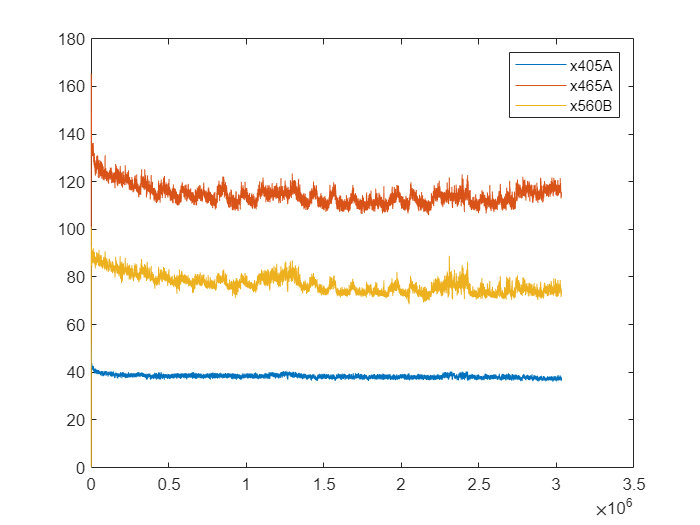

signalFibPho1 = {'x405A','x465A','x560B'};
for i= signalFibPho1
    plot(data.streams.(i{:}).data);
    hold on;
end
hold off;
legend(signalFibPho1);

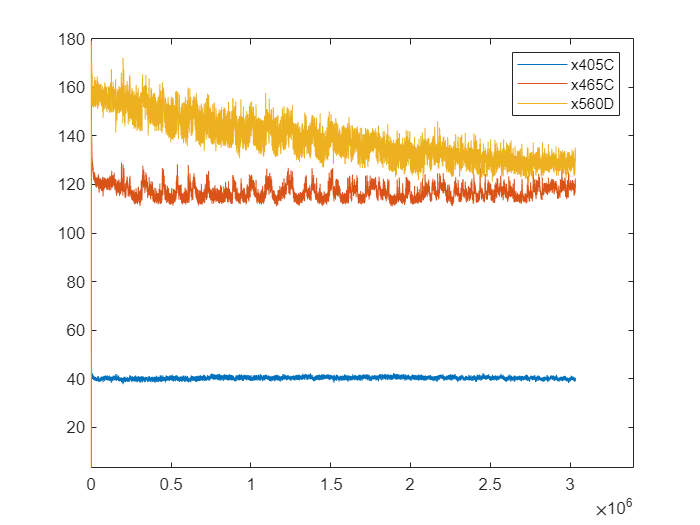

slope = data.streams.('x405C').data
signalFibPho2 = {'x405C','x465C','x560D'};
for i= signalFibPho2
    plot(data.streams.(i{:}).data);
    hold on;
end
hold off;
legend(signalFibPho2);

## Normalized Data

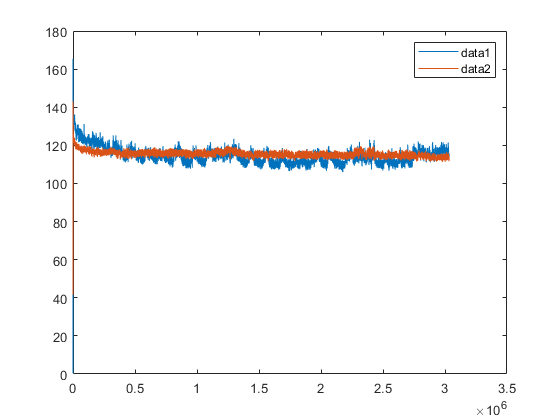

signalFibPho1 = {'x405A','x465A','x560B'};
x405 = data.streams.(signalFibPho1{1}).data;
x465 = data.streams.(signalFibPho1{2}).data;
x560 = data.streams.(signalFibPho1{3}).data;

[x465N1,x560N1] = getNormalizedSignal(x405,x465,x560);
figure;
plot(x465);
hold on;
plot(x465N1);
legend
hold off;

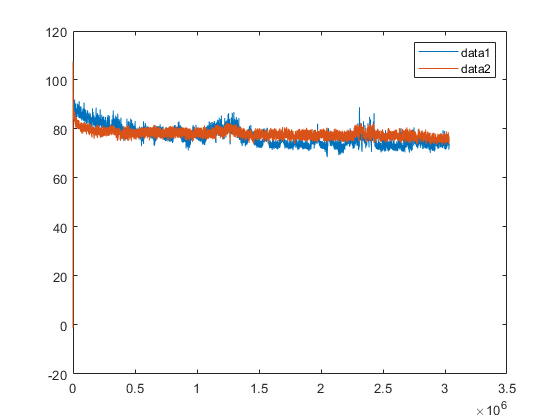

plot(x560);
hold on;
plot(x560N1);
legend;
hold off;

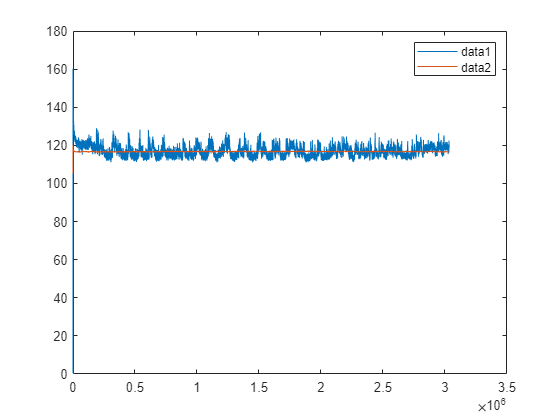


signalFibPho2 = {'x405C','x465C','x560D'};
x405 = data.streams.(signalFibPho2{1}).data;
x465 = data.streams.(signalFibPho2{2}).data;
x560 = data.streams.(signalFibPho2{3}).data;

[x465N2,x560N2] = getNormalizedSignal(x405,x465,x560);
plot(x465);
hold on;
plot(x465N2);
hold off;
legend

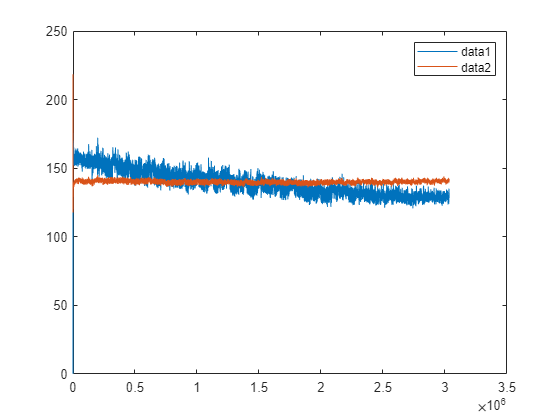

Undefined variable 'IdChannel'.

plot(x560);
hold on;
plot(x560N2);
legend;
hold off;